## Adaptation du réseau neuronal 

net = googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


lay = net.Layers

lay =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution                  

inLayer = lay(1)

inLayer =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inSize = inLayer.InputSize

inSize =    224   224     3


lgraph = layerGraph(net);
newFc = fullyConnectedLayer(10,"Name","new_fc");
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newOut = classificationLayer("Name","new_out");
lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Image datastores

imds = imageDatastore("img2", "IncludeSubfolders",true, "LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\00705aa7-5ea2-4419-9440-8ba65e108eb9___FREC_Pwd.M 0267.JPG';
                              ' ...\00705aa7-5ea2-4419-9440-8ba65e108eb9___FREC_Pwd.M 0267_flipLR.JPG';
                              ' ...\00b7df55-c789-43d6-a02e-a579ac9d07e6___FREC_Pwd.M 4748.JPG'
                               ... and 18044 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2'
                              }
                      Labels: [Cherry_(including_sour)___Powdery_mildew; Cherry_(including_sour)___Powdery_mildew; Cherry_(including_sour)___Powdery_mildew ... and 18044 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "

imds.Labels

ans = 18047×1 categorical array
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)___Powdery_mildew 
     Cherry_(including_sour)

[trainAllImgs, testAllImgs] = splitEachLabel(imds, 0.7, "randomized")

trainAllImgs =   ImageDatastore with properties:

                       Files: {
                              ' ...\00b7df55-c789-43d6-a02e-a579ac9d07e6___FREC_Pwd.M 4748.JPG';
                              ' ...\00d12ac0-a293-47e0-a4c6-a80f37204c39___FREC_Pwd.M 4812.JPG';
                              ' ...\00d12ac0-a293-47e0-a4c6-a80f37204c39___FREC_Pwd.M 4812_flipLR.JPG'
                               ... and 12629 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2'
                              }
                      Labels: [Cherry_(including_sour)___Powdery_mildew; Cherry_(including_sour)___Powdery_mildew; Cherry_(including_sour)___Powdery_mildew ... and 12629 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jp

testAllImgs =   ImageDatastore with properties:

                       Files: {
                              ' ...\00705aa7-5ea2-4419-9440-8ba65e108eb9___FREC_Pwd.M 0267.JPG';
                              ' ...\00705aa7-5ea2-4419-9440-8ba65e108eb9___FREC_Pwd.M 0267_flipLR.JPG';
                              ' ...\00b7df55-c789-43d6-a02e-a579ac9d07e6___FREC_Pwd.M 4748_flipLR.JPG'
                               ... and 5412 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2'
                              }
                      Labels: [Cherry_(including_sour)___Powdery_mildew; Cherry_(including_sour)___Powdery_mildew; Cherry_(including_sour)___Powdery_mildew ... and 5412 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"   

pour travailler sur une partie des images et pas sur la totalité

nFiles = length(trainAllImgs.Files);
RandIndices = randperm(nFiles);
indices = RandIndices(1:2000)

indices =        10907       12155        6104       10537       10105       11573        6284       10807        9444        3017        1708        5091        9487        2099        5245        8031        3177         843       11652        7282        1955        4626       10711        4642        1216        6813        5025        4503        5068        8808        8899        8399        9363       11582        1205         575        6105        7203        9492        2837        3140        2625         686        1373        9785        4806       11036       10460         303       10419


trainPartImg = subset(trainAllImgs,indices)

trainPartImg =   ImageDatastore with properties:

                       Files: {
                              ' ...\8ce6eb35-a7e2-4839-b923-95fde1635aa5___FAM_L.Blight 4716.JPG';
                              ' ...\9268b279-6e48-45ec-98b9-58475d9466e8___Mt.N.V_HL 9132_90deg.JPG';
                              ' ...\e521bbbd-09cd-4ff3-9060-60491b8128b0___RS_NLB 4005_flipTB.JPG'
                               ... and 1997 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2'
                              }
                      Labels: [Grape___Leaf_blight_(Isariopsis_Leaf_Spot); Grape___healthy; Corn_(maize)___Northern_Leaf_Blight ... and 1997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
   

trainPartImg.Files

ans = 2000×1 cell array
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2\Grape___Leaf_blight_(Isariopsis_Leaf_Spot)\8ce6eb35-a7e2-4839-b923-95fde1635aa5___FAM_L.Blight 4716.JPG'                  }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2\Grape___healthy\9268b279-6e48-45ec-98b9-58475d9466e8___Mt.N.V_HL 9132_90deg.JPG'                                          }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2\Corn_(maize)___Northern_Leaf_Blight\e521bbbd-09cd-4ff3-9060-60491b8128b0___RS_NLB 4005_flipTB.JPG'                        }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2\Grape___Leaf_blight_(Isariopsis_Leaf_Spot)\3b31ce15-2e27-4d3c-acff-bb2f72204048___FAM_L.Blight 1522.JPG'                  }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2\Grape___Esca_(Black_Measles)\ea3ab184-6e2e-4c90-acee-c3f8b4f755a9___FAM_B.Msls 1118_flipLR.JPG'                           }
    {'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2\Grape___healthy\17572261-c800-42b7-8ba

nFiles = length(testAllImgs.Files);
RandIndices = randperm(nFiles);
indices = RandIndices(1:400)

indices =         5126        1191        5373        3228          77        1248        1490        2969        5110        1816        2341        2256        4256        1255         422        1635        2988        3054        3877        1439        1727        4483        4198        4873        2245         415          56        4607        3485        5173        4418        1477         812        3093        4659        3925        1941        1263        4527        2345        3394        2632         817        3479        1641        3017        1683        4832        3570        3610


testPartImg  = subset (testAllImgs, indices)

testPartImg =   ImageDatastore with properties:

                       Files: {
                              ' ...ad9d58-7f7e-4a4c-8ced-fec8d23d9a7e___Mt.N.V_HL 6170_new30degFlipLR.JPG';
                              ' ...\4be4a686-ab64-43d7-9d7c-0939e389aac9___RS_GLSp 9338_90deg.JPG';
                              ' ...\e949f6bb-cda7-4824-9a97-67337fc164a5___Mt.N.V_HL 6156_180deg.JPG'
                               ... and 397 more
                              }
                     Folders: {
                              'D:\cecile\Prof\Matlab\SI-IA-PlantDiseases\img2'
                              }
                      Labels: [Grape___healthy; Corn_(maize)___Cercospora_leaf_spot Gray_leaf_spot; Grape___healthy ... and 397 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
        

trainds = augmentedImageDatastore([224 224],trainPartImg);
testds = augmentedImageDatastore([224 224],testPartImg);

## Entraînement du réseau

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:10 |       10.94% |       4.8996 |          0.0100 |
|       2 |          50 |       00:06:02 |       98.44% |       0.0607 |          0.0100 |
|       4 |         100 |       00:12:05 |      100.00% |       0.0359 |          0.0100 |
|       5 |         150 |       00:18:02 |      100.00% |       0.0011 |          0.0100 |
|       7 |         200 |       00:24:02 |      100.00% |       0.0006 |          0.0100 |
|       9 |         250 |       00:30:00 |      100.00% |       0.0001 |          0.0100 |
|      10 |         300 |  

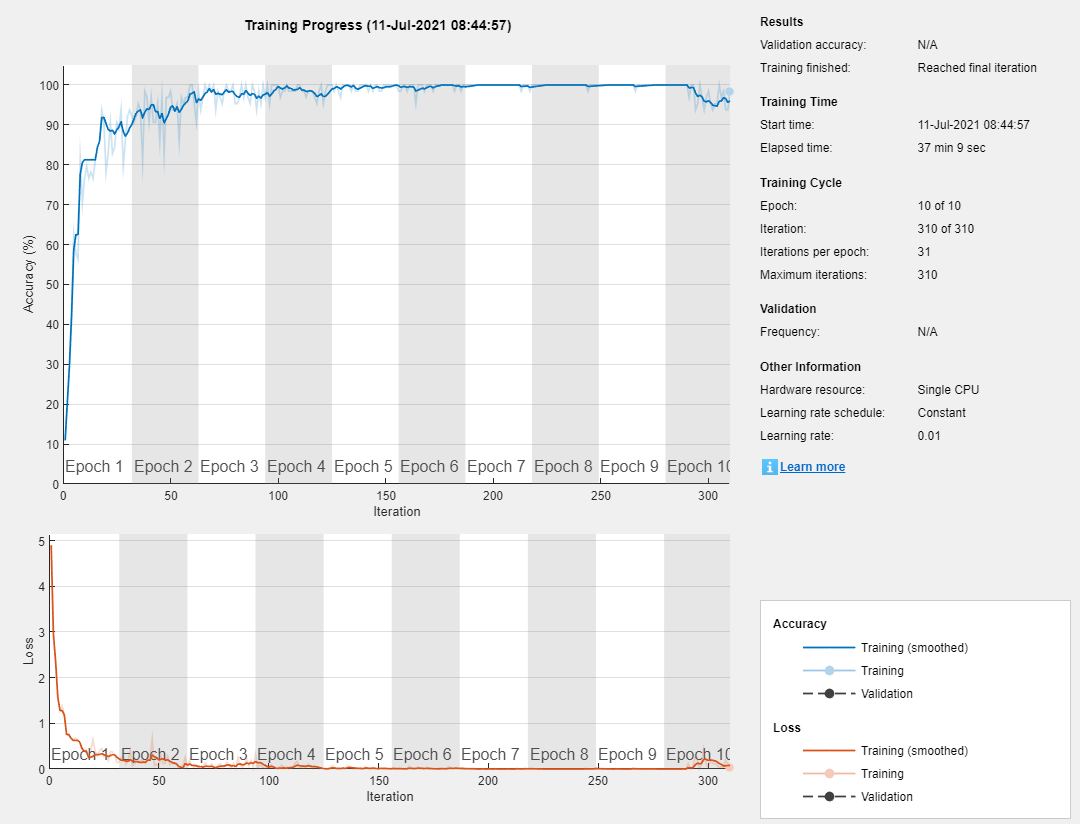

plantnet10 =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


options = trainingOptions("sgdm",...
    'InitialLearnRate', 0.01, ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'MaxEpochs',10, ...
    'MiniBatchSize',64, ...
    'Plots','training-progress',...
    'Shuffle','every-epoch');
    
plantnet10 = trainNetwork(trainds,lgraph,options)

save ("plantnet10")

## Evaluation du réseau sur les données de test

load('plantnet10.mat')
predictions = classify(plantnet10,testds)

predictions = 400×1 categorical array
     Grape___healthy 
     Corn_(maize)___Cercospora_leaf_spot Gray_leaf_spot 
     Grape___healthy 
     Corn_(maize)___healthy 
     Cherry_(including_sour)___Powdery_mildew 
     Corn_(maize)___Cercospora_leaf_spot Gray_leaf_spot 
     Corn_(maize)___Cercospora_leaf_spot Gray_leaf_spot 
     Corn_(maize)___healthy 
     Grape___healthy 
     Corn_(maize)___Common_rust_ 
     Corn_(maize)___Northern_Leaf_Blight 
     Corn_(maize)___Northern_Leaf_Blight 
     Grape___Esca_(Black_Measles) 
     Corn_(maize)___Cercospora_leaf_spot Gray_leaf_spot 
     Cherry_(including_sour)___Powdery_mildew 
     Corn_(maize)___Common_rust_ 
     Corn_(maize)___healthy 
     Corn_(maize)___healthy 
     Grape___Esca_(Black_Measles) 
     Corn_(maize)___Cercospora_leaf_spot Gray_leaf_spot 
     Corn_(maize)___Common_rust_ 
     Grape___Leaf_blight_(Isariopsis_Leaf_Spot) 
     Grape___Esca_(Black_Measles) 
     Grape___Leaf_blight_(Isariopsis_Leaf_Spot) 
     Corn_(m

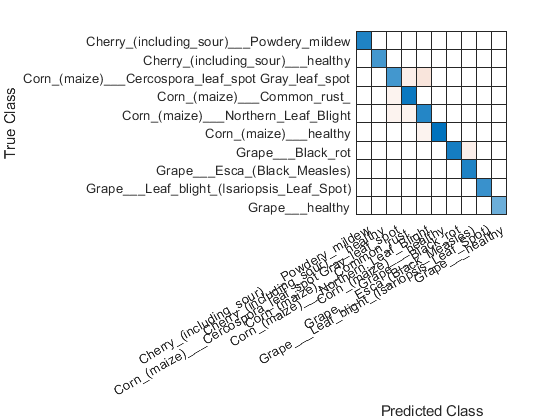

confusionchart(testPartImg.Labels, predictions)

## Temps d'exécution sur une image

img = imread("img/Corn__Cercospora_leaf_spot Gray_leaf_spot/0a01cc10-3892-4311-9c48-0ac6ab3c7c43___RS_GLSp 9352.JPG" );
img = imresize(img, [224,224]);
tic
label = classify (plantnet10,img)

label = categorical
     Corn_(maize)___Northern_Leaf_Blight 


toc

Elapsed time is 1.370296 seconds.
